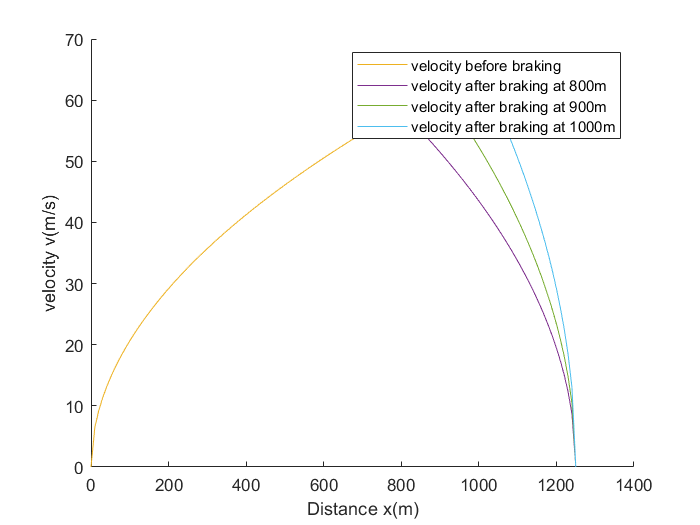

% the following plots and equations model the velocity vs distance 
% ideal behaviour of the hyperloop pod 

% should be used for analysis purposes and esstimations only, because
% the model might be incomplete

% here is ploted based on the respective intervals
% of each acceleration, the speed of the pod 

% three cases have been taken: 1. it starts braking at 800m
%                              2. it starts braking at 900m
%                              3. it starts braking at 1000m


clear
clc
%input arguments 

mass = 200; %in Kg

Force = 425.754; %in Newton

s = [800, 900, 1000]; %different values for braking distance

d=1250; %the total distance

acceleration = pod_acceleration(mass,Force);

top_Speed = top_speed(acceleration,s);

decceleration = acceleration_of_brakes(top_Speed,s,d);

braking_force = decceleration.*mass;

x11= 0:10:800;
x12= 0:10:900;
x13= 0:10:1000;

x21 = 800:10:1250;
x22 = 900:10:1250;
x23 = 1000:10:1250;

v11 = sqrt(2*acceleration.*x11);
v12 = sqrt(2*acceleration.*x12);
v13 = sqrt(2*acceleration.*x13);

v21 = sqrt(top_Speed(1)^2-2*decceleration(1)*(x21-s(1)));%case 1 
v22 = sqrt(top_Speed(2)^2-2*decceleration(2)*(x22-s(2)));% case 2
v23 = sqrt(top_Speed(3)^2-2*decceleration(3)*(x23-s(3)));% case 3 


figure(1)
hold on

p1 = plot(x11,v11);
p2 = plot(x12,v12);
p3 = plot(x13,v13);

p4 = plot(x21,v21);
p5 = plot(x22,v22);
p6 = plot(x23,v23);

legend([p3 p4 p5 p6 ],'velocity before braking','velocity after braking at 800m',...
    'velocity after braking at 900m','velocity after braking at 1000m');

xlabel('Distance x(m)');
ylabel('velocity v(m/s)');

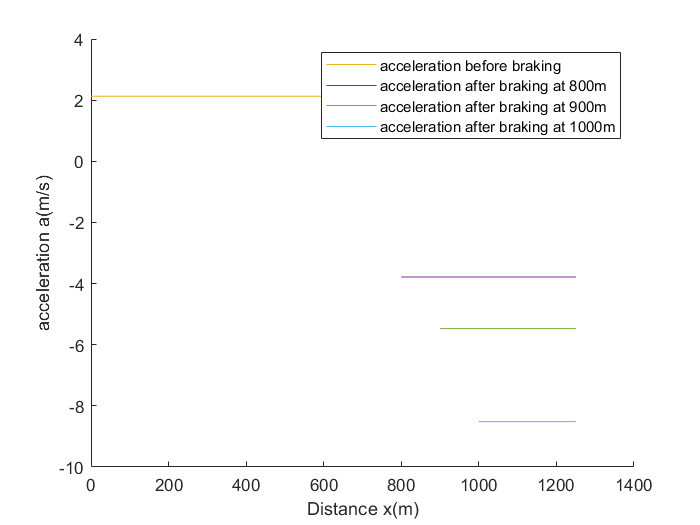



a11 = acceleration*ones(1,81);
a12 = acceleration*ones(1,91);
a13 = acceleration*ones(1,101);

a21 = decceleration(1)*ones(1,46);
a22 = decceleration(2)*ones(1,36);
a23 = decceleration(3)*ones(1,26);

figure(2)
hold on

p11 = plot(x11,a11);
p22 = plot(x12,a12);
p33 = plot(x13,a13);

p44 = plot(x21,-a21);
p55 = plot(x22,-a22);
p66 = plot(x23,-a23);

legend([p33 p44 p55 p66 ],'acceleration before braking','acceleration after braking at 800m',...
    'acceleration after braking at 900m','acceleration after braking at 1000m');

xlabel('Distance x(m)');
ylabel('acceleration a(m/s)');
hold off

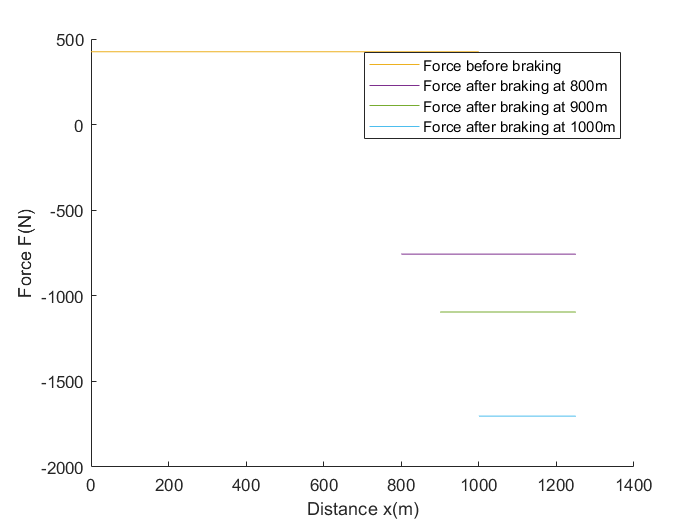


figure(3)
hold on

p111 = plot(x11,mass*a11);
p222 = plot(x12,mass*a12);
p333 = plot(x13,mass*a13);

p444 = plot(x21,-mass*a21);
p555 = plot(x22,-mass*a22);
p666 = plot(x23,-mass*a23);

legend([p333 p444 p555 p666],'Force before braking','Force after braking at 800m',...
    'Force after braking at 900m','Force after braking at 1000m');

xlabel('Distance x(m)');
ylabel('Force F(N)');
hold off